# Case Isolation & Tracing

## Symptomatic Ascertainment Rate

- Symptomatic ascertainment rate from [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7577796/pdf/12916_2020_Article_1790.pdf,](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7577796/pdf/12916_2020_Article_1790.pdf,) data from repo at [https://github.com/thimotei/covid_underreporting/tree/master/data](https://github.com/thimotei/covid_underreporting/tree/master/data) 

- Incidence data from [https://www.ecdc.europa.eu/en/publications-data/download-todays-data-geographic-distribution-covid-19-cases-worldwide](https://www.ecdc.europa.eu/en/publications-data/download-todays-data-geographic-distribution-covid-19-cases-worldwide) (used in above)

- Testing data from [https://ourworldindata.org/coronavirus-testing](https://ourworldindata.org/coronavirus-testing) 

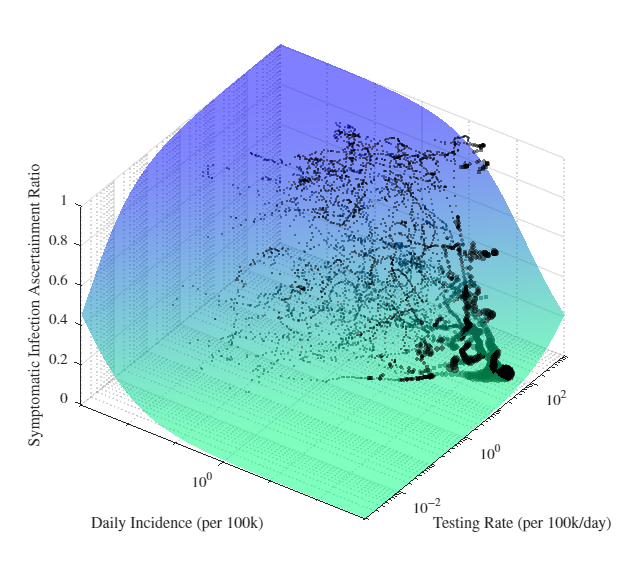

% read in data
ascer = readtable('../../../Data/Preparedness/10.under_ascertainment_estimates.csv');
cases = readtable('../../../Data/Preparedness/10.COVID-19-geographic-disbtribution-worldwide-2020-12-14.xlsx');
tests = readtable('../../../Data/Preparedness/10.testing.csv');

% fill in empty location codes
cases.countryterritoryCode(strcmp(cases.countryterritoryCode,'')) = cases.geoId(strcmp(cases.countryterritoryCode,''));
tests.ISOCode(strcmp(tests.ISOCode,'OWID_KOS'))                   = {'XKX'};
tests.ISOCode(strcmp(tests.Entity,'Benin'))                       = {'BEN'};
tests.ISOCode(strcmp(tests.Entity,'Comoros'))                     = {'COM'};
tests.ISOCode(strcmp(tests.Entity,'Eritrea'))                     = {'ERI'};
tests.ISOCode(strcmp(tests.Entity,'Liberia'))                     = {'LBR'};
tests.ISOCode(strcmp(tests.Entity,'Mauritius'))                   = {'MUS'};
tests.ISOCode(strcmp(tests.Entity,'Papua New Guinea'))            = {'PNG'};
tests.ISOCode(strcmp(tests.Entity,'Singapore'))                   = {'SGP'};
tests.ISOCode(strcmp(tests.Entity,'Somalia'))                     = {'SOM'};

% make date format consistent
cases.dateRep.Format = 'yyyy-MM-dd';
tests.Date.Format    = 'yyyy-MM-dd';

% add rows for missing dates
[group,codes] = grp2idx(cases.countryterritoryCode);
maxrange      = splitapply(@(x) [min(x),max(x)], cases.dateRep, group);
actualdates   = splitapply(@(x) {x}, cases.dateRep, group);
for i = 1:length(codes);
    country = codes(i);
    missing = setdiff([maxrange(i,1):maxrange(i,2)],actualdates{i});

    if ~isempty(missing);
        blanks = table(missing',...
                       nan(length(missing),1),nan(length(missing),1),nan(length(missing),1),nan(length(missing),1),nan(length(missing),1),...
                       cell(length(missing),1),cell(length(missing),1),...
                       repelem(country,length(missing),1), ...
                       nan(length(missing),1), ...
                       cell(length(missing),1), ...
                       nan(length(missing),1));
        blanks.Properties.VariableNames = cases.Properties.VariableNames;
        cases = [cases;blanks];
    end
end
cases = sortrows(cases, {'countryterritoryCode', 'dateRep'});

[group,codes] = grp2idx(tests.ISOCode);
maxrange      = splitapply(@(x) [min(x),max(x)], tests.Date, group);
actualdates   = splitapply(@(x) {x}, tests.Date, group);
for i = 1:length(codes);
    country = codes(i);
    missing = setdiff([maxrange(i,1):maxrange(i,2)],actualdates{i});

    if ~isempty(missing);
        blanks = table(cell(length(missing),1),repelem(country,length(missing),1),...
                       missing',...
                       cell(length(missing),1),cell(length(missing),1),...
                       nan(length(missing),1),nan(length(missing),1),nan(length(missing),1),...
                       nan(length(missing),1),nan(length(missing),1),nan(length(missing),1),...
                       nan(length(missing),1),nan(length(missing),1),nan(length(missing),1));
        blanks.Properties.VariableNames = tests.Properties.VariableNames;
        tests = [tests;blanks];
    end
end
tests = sortrows(tests, {'ISOCode', 'Date'});
% test = splitapply(@(x) {x}, tests.Date, grp2idx(tests.ISOCode)); %this is just a test to see if we have any missing dates: output should be false 
% for i = 1:length(test);
%     test1(i) = length(test{i});%number of dates we have data for
% end
% test1 = test1';
% test2 = splitapply(@(x) length(min(x):max(x)), tests.Date, grp2idx(tests.ISOCode));
% any(test1~=test2)

% align dates 
ascer.dateRep = ascer.date - days(13);%this is day of reporting corresponding to ascertainment rates

% quantities
cases.cases(cases.cases<0) = NaN;
cases.estimate = 10^5*cases.cases./cases.popData2019;%(reported) incidence per 100k
[group,codes]  = grp2idx(cases.countryterritoryCode);
estimate       = splitapply(@(x) {movmean(x,7,'omitnan')}, cases.estimate, group);%take the 7-day moving average (in order to correct for under-ascertainment)
cases.estimate = vertcat(estimate{:});
for i = 1:length(codes);
    country  = codes(i);

    asc_date = ascer.date(strcmp(ascer.iso_code,country));
    asc_val  = ascer.estimate(strcmp(ascer.iso_code,country));%this is proportion of cases that died on day t that were ascertained (per paper SI)

    dth_date = cases.dateRep(strcmp(cases.countryterritoryCode,country)) + days(13);%date that incident cases expected to die
    cas_val  = cases.estimate(strcmp(cases.countryterritoryCode,country));
    
    aasc_val       = nan(size(cas_val));
    [indc,inda]    = ismember(dth_date,asc_date);%check for ascertainment estimates for the corresponding date of death
    aasc_val(indc) = asc_val(inda(inda~=0));

    cases.estimate(strcmp(cases.countryterritoryCode,country)) = cas_val./aasc_val;%correct for under-ascertainment
end
cases.estimate             = cases.estimate/0.50;%correct for asymptomatic cases (per paper SI)

tests.estimate = 100*tests.DailyChangeInCumulativeTotalPerThousand;%tests per 100k
[group,codes]  = grp2idx(tests.ISOCode);
estimate       = splitapply(@(x) {movmean(x,7,'omitnan')}, tests.estimate, group);%take the 7-day moving average
tests.estimate = vertcat(estimate{:});

% common data
ascer.common = strcat(ascer.iso_code,cellstr(ascer.dateRep));
cases.common = strcat(cases.countryterritoryCode,cellstr(cases.dateRep));
tests.common = strcat(tests.ISOCode,cellstr(tests.Date));
common_data  = intersect(intersect(ascer.common, cases.common),tests.common);
ascer        = ascer(ismember(ascer.common, common_data),:);
cases        = cases(ismember(cases.common, common_data),:);
tests        = tests(ismember(tests.common, common_data),:);
% all(strcmp(ascer.iso_code,cases.countryterritoryCode))
% all(ascer.dateRep==cases.dateRep)
% figure;bar(ascer.dateRep(strcmp(ascer.iso_code,'IRL')),100*ascer.estimate(strcmp(ascer.iso_code,'IRL')));
% figure;bar(cases.dateRep(strcmp(cases.countryterritoryCode,'IRL')),cases.estimate(strcmp(cases.countryterritoryCode,'IRL')));
% figure;bar(tests.Date(strcmp(tests.ISOCode,'IRL')),tests.estimate(strcmp(tests.ISOCode,'IRL')));
isnotna      = ~isnan(ascer.estimate)&~isnan(cases.estimate)&~isnan(tests.estimate);
ascer        = ascer(isnotna,:);
cases        = cases(isnotna,:);
tests        = tests(isnotna,:);
x            = cases.estimate;
y            = tests.estimate;
z            = ascer.estimate;
w            = cases.estimate;%daily incidence akin to sample size (denominator in ascertainment)

% fits
% customfit2d     = fittype('1/(1+exp(a+b*log10(x)))');%proportion, monotonic function
% options         = fitoptions(customfit2d);
% options.Weights = w;
% [mdl,~]         = fit(x,z,customfit2d,options);
% f = figure('Units','centimeters','Position',[0 0 15 12]);
% hold on;
% msize  = max(0.1,2*w);
% scatter(x,z,msize,'r.');
% xRange = logspace(-3,3,1000);
% zFit   = feval(mdl,xRange);
% plot(xRange,zFit,'b-');
% set(gca,'XScale','log');
% grid on;
% xlabel('Daily Incidence (per 100k)');
% ylabel('Ascertainment Rate');
% [mdl,~]         = fit(y,z,customfit2d,options);
% f = figure('Units','centimeters','Position',[0 0 15 12]);
% hold on;
% msize  = max(0.1,2*w);
% scatter(y,z,msize,'r.');
% yRange = logspace(-3,3,1000);
% zFit   = feval(mdl,yRange);
% plot(yRange,zFit,'b-');
% set(gca,'XScale','log');
% grid on;
% xlabel('Daily Testing (per 100k)');
% ylabel('Ascertainment Rate');
customfit3d     = fittype('1/(1+exp(a+b*log10(x)+c*log10(y)))',...
                          'dependent',{'z'},'independent',{'x','y'},'coefficients',{'a','b','c'});%proportion, monotonic function
options         = fitoptions(customfit3d);
options.Weights = w;
[mdl,~]         = fit([x,y],z,customfit3d,options);%%%
xRange          = logspace(-3,3,1000);
yRange          = logspace(-3,3,1000);
[X,Y]           = meshgrid(xRange,yRange);
asc_s           = reshape(feval(mdl,X(:),Y(:)),size(X));

% figures
f = figure('Units','centimeters','Position',[0 0 15 14]);
set(f,'defaulttextInterpreter','latex');
set(f,'defaultAxesTickLabelInterpreter','latex');
set(f,'defaultLegendInterpreter','latex');
hold on;
msize = max(0.1,2*w);
scatter3(x,y,z,msize,'k.');
surf(X,Y,asc_s);
colormap(flipud(winter));
shading interp;
alpha 0.5;
set(gca,'XScale','log');
set(gca,'YScale','log');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Incidence (per 100k)');
ylabel('Testing Rate (per 100k/day)');
zlabel('Symptomatic Infection Ascertainment Ratio');
view(35,45);
vec_pos = get(get(gca,'xlabel'),'Position');
set(get(gca,'xlabel'),'Position',vec_pos + [-4.5 0 0.05]);
vec_pos = get(get(gca,'ylabel'),'Position');
set(get(gca,'ylabel'),'Position',vec_pos + [0 1.5 0]);

## Ascertainment Method

Ascertainment method data from:

- China [https://www.science.org/doi/10.1126/science.abe2424](https://www.science.org/doi/10.1126/science.abe2424) (2020 population data from [https://www.statista.com/statistics/1391700/china-population-of-hunan-province/](https://www.statista.com/statistics/1391700/china-population-of-hunan-province/)) 

- Singapore [https://www.cdc.gov/mmwr/volumes/69/wr/pdfs/mm6911e1-H.pdf](https://www.cdc.gov/mmwr/volumes/69/wr/pdfs/mm6911e1-H.pdf) (2020 population data from [https://tablebuilder.singstat.gov.sg/table/TS/M810001](https://tablebuilder.singstat.gov.sg/table/TS/M810001)) 

- Note that this is slightly different to linked/unlinked cases: all traced contacts are linked, but not all linked cases are traced

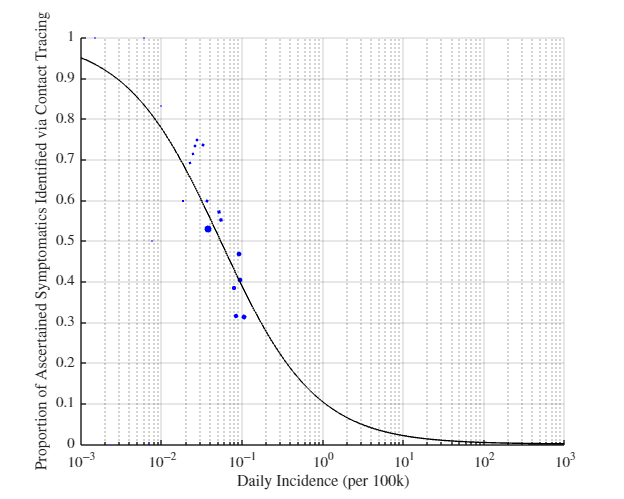

% read in CHN data
data = readtable('../../../Data/Preparedness/10.incidence_time_series_by_case_ascertainment.csv');

% quantities
x = ((data.passive_surveillance/0.6450)+data.contact_tracing)/664.5;%daily incidence per 100k, unadjusted for underascertainment but adjusted for asymptomatic cases (per paper SI)
y = data.contact_tracing./(data.passive_surveillance + data.contact_tracing);%of those ascertained, the proportion ascertained via contact tracing
w = data.passive_surveillance + data.contact_tracing;%weighted by sample size, i.e. absolute values of daily incidence

% dates only from phases 2 & 3
x = x(data.t>=27);
y = y(data.t>=27);
w = w(data.t>=27);

% add SGP data
x = [x;100/46/56.85807];%cases/time period (14-Jan to 28-Feb)/per 100k
y = [y;0.53];
w = [w;100];

% fits
customfit2d     = fittype('1/(1+exp(a+b*log10(x)))');%proportion, monotonic function
options         = fitoptions(customfit2d);
options.Weights = w;
[mdl,~]         = fit(x,y,customfit2d,options);%%%
meth            = reshape(feval(mdl,X(:)),size(X));

% figures
% f = figure('Units','centimeters','Position',[0 0 15 12]);
% hold on;
% bar(data.t, [data.passive_surveillance,data.contact_tracing], 'stacked');
% grid on;
% xlabel('Day of Onset');
% ylabel('Incidence');
% legend('Identified via Symptoms','Identified via Tracing');
f = figure('Units','centimeters','Position',[0 0 15 12]);
set(f,'defaulttextInterpreter','latex');
set(f,'defaultAxesTickLabelInterpreter','latex');
set(f,'defaultLegendInterpreter','latex');
hold on;
msize = max(0.1,2*w);
scatter3(x,x,y,msize,'b.');
surf(X,Y,meth);
set(gca,'XScale','log');
set(gca,'YScale','log');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Incidence (per 100k)');
ylabel('');
zlabel('Proportion of Ascertained Symptomatics Identified via Contact Tracing');
view(0,0);

## Asymptomatic Ascertainment Rate

Assumptions:

- AAR of those ascertained via symptoms is 0

- AAR of those ascertained via contact tracing equal to SAR

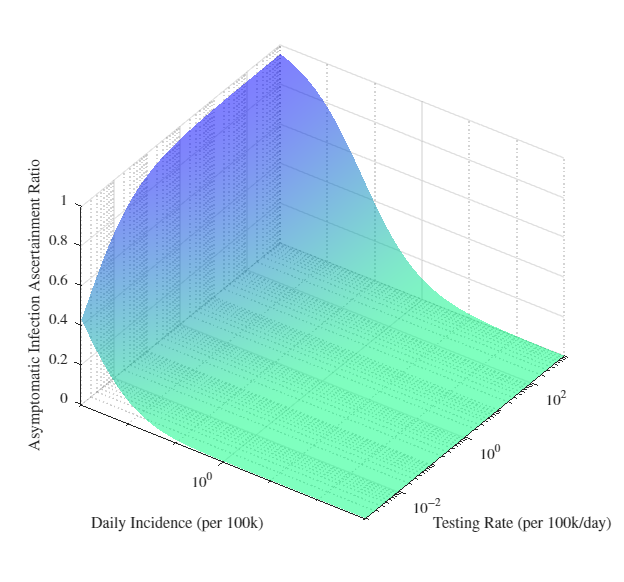

asc_a = meth.*asc_s;%%%

% figures
f = figure('Units','centimeters','Position',[0 0 15 14]);
set(f,'defaulttextInterpreter','latex');
set(f,'defaultAxesTickLabelInterpreter','latex');
set(f,'defaultLegendInterpreter','latex');
hold on;
surf(X,Y,asc_a);
colormap(flipud(winter));
shading interp;
alpha 0.5;
set(gca,'XScale','log');
set(gca,'YScale','log');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Incidence (per 100k)');
ylabel('Testing Rate (per 100k/day)');
zlabel('Asymptomatic Infection Ascertainment Ratio');
view(35,45);
vec_pos = get(get(gca,'xlabel'),'Position');
set(get(gca,'xlabel'),'Position',vec_pos + [-4.5 0 0.05]);
vec_pos = get(get(gca,'ylabel'),'Position');
set(get(gca,'ylabel'),'Position',vec_pos + [0 1.5 0]);

## Adjusted Ascertainment Rates

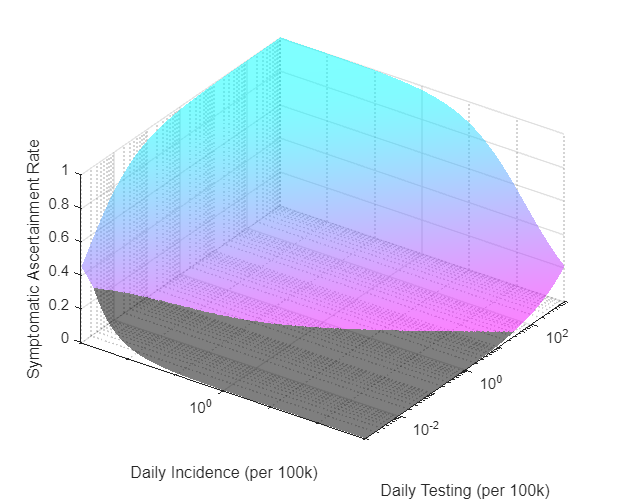

% upper bounds
% ub  = Y./X;%max ascertainment rate = testing rate/incidence rate: you can't ascertain more cases than you can test
%            %test positivity rate = (X.*Z)./Y = 100% in this region
ps    = 0.6;
ub_s  = (Y./X).*(1*(1-meth) + ps*meth);%%%
ub_a  = (Y./X).*(0*(1-meth) + (1-ps)*meth);%%%
asc_s = min(asc_s,ub_s);
asc_a = min(asc_a,ub_a);

% plotting
ub_s(ub_s>asc_s) = NaN;
ub_a(ub_a>asc_a) = NaN;

% figures
f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
surf(X,Y,asc_s);
colormap(flipud(cool));
shading interp;
alpha 0.5;
surf(X,Y,ub_s,'FaceColor','k','EdgeColor','none','FaceAlpha',0.5);
set(gca,'XScale','log');
set(gca,'YScale','log');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Incidence (per 100k)');
ylabel('Daily Testing (per 100k)');
zlabel('Symptomatic Ascertainment Rate');
view(35,45);

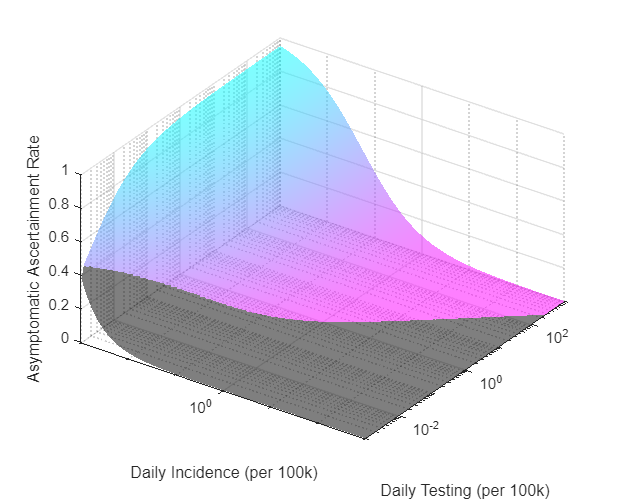

f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
surf(X,Y,asc_a);
colormap(flipud(cool));
shading interp;
alpha 0.5;
surf(X,Y,ub_a,'FaceColor','k','EdgeColor','none','FaceAlpha',0.5);
set(gca,'XScale','log');
set(gca,'YScale','log');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Incidence (per 100k)');
ylabel('Daily Testing (per 100k)');
zlabel('Asymptomatic Ascertainment Rate');
view(35,45);

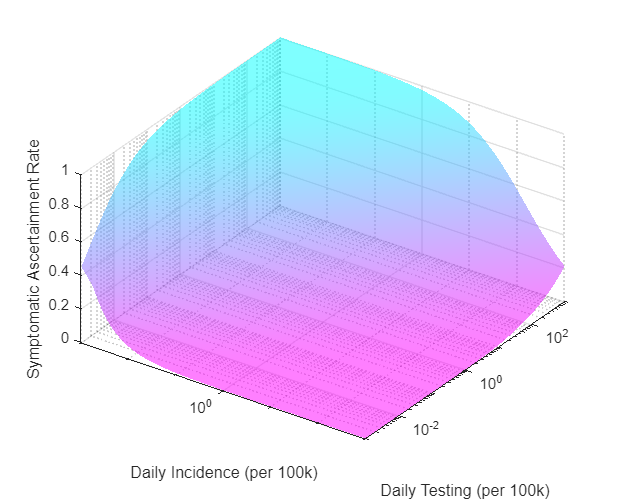

% lower bounds
% lb  = Y.*(#./N)./X;%min ascertainment rate = testing rate*prevalence/incidence rate: you can't ascertain fewer cases than random sampling
%                    %we can approximate I./N with X/10^5
lb_s  = Y/10^5.*(1*(1-meth) + ps*meth);%%%
lb_a  = Y/10^5.*(0*(1-meth) + (1-ps)*meth);%%%
asc_s = max(lb_s,asc_s);
asc_a = max(lb_a,asc_a);

% plotting
lb_s(lb_s<asc_s) = NaN;
lb_a(lb_a<asc_a) = NaN;

% figures
f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
surf(X,Y,asc_s);
colormap(flipud(cool));
shading interp;
alpha 0.5;
surf(X,Y,lb_s,'FaceColor','k','EdgeColor','none','FaceAlpha',0.5);
set(gca,'XScale','log');
set(gca,'YScale','log');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Incidence (per 100k)');
ylabel('Daily Testing (per 100k)');
zlabel('Symptomatic Ascertainment Rate');
view(35,45);

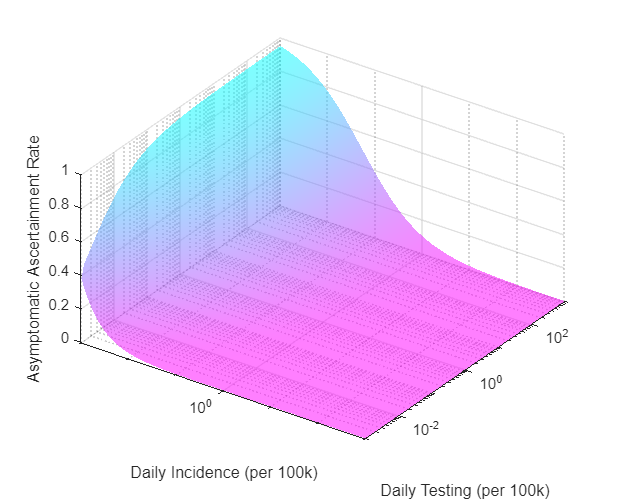

f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
surf(X,Y,asc_a);
colormap(flipud(cool));
shading interp;
alpha 0.5;
surf(X,Y,lb_a,'FaceColor','k','EdgeColor','none','FaceAlpha',0.5);
set(gca,'XScale','log');
set(gca,'YScale','log');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Incidence (per 100k)');
ylabel('Daily Testing (per 100k)');
zlabel('Asymptomatic Ascertainment Rate');
view(35,45);

## Symptom-Ascertained Transmission Multiplier

For those ascertained via symptoms (symptomatic only), the transmission multiplier depends on the onset-PCR result delay, with data from:

- Meta-analysis [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9233872/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9233872/) 

- MX and COL [https://clinicalandtranslationalinvestigation.com/files/ric_22_74_2_071-080.pdf](https://clinicalandtranslationalinvestigation.com/files/ric_22_74_2_071-080.pdf) 

- CN (symptom-based) [https://www.sciencedirect.com/science/article/pii/S1473309920302875?via%3Dihub](https://www.sciencedirect.com/science/article/pii/S1473309920302875?via%3Dihub) 

- UK (Pillar 2 only) onset-booking (symptomatic-positve only) and booking-result are respectively [https://www.ons.gov.uk/peoplepopulationandcommunity/healthandsocialcare/conditionsanddiseases/bulletins/coronaviruscovid19testingbehavioursandoutcomesengland/september2020tonovember2021](https://www.ons.gov.uk/peoplepopulationandcommunity/healthandsocialcare/conditionsanddiseases/bulletins/coronaviruscovid19testingbehavioursandoutcomesengland/september2020tonovember2021) [https://www.gov.uk/government/publications/weekly-statistics-for-nhs-test-and-trace-england-18-to-24-november-2021](https://www.gov.uk/government/publications/weekly-statistics-for-nhs-test-and-trace-england-18-to-24-november-2021)

- Testing data from [https://ourworldindata.org/coronavirus-testing](https://ourworldindata.org/coronavirus-testing)

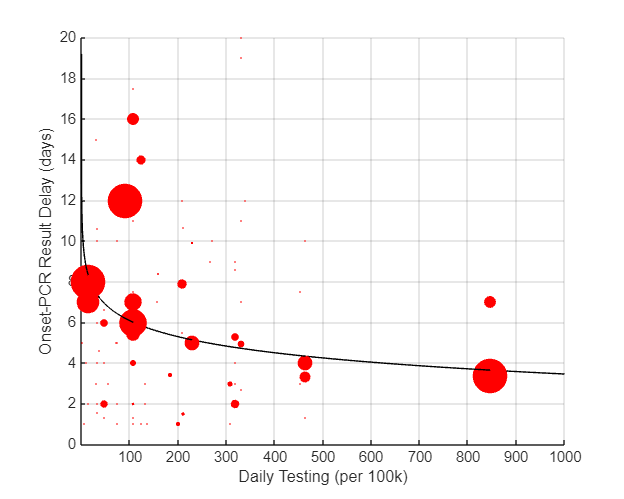

% read in delay data
data      = readtable('../../../Data/Preparedness/10.Delay meta.csv');
countries = data.Country;

% read in testing data
T = readtable('../../../Data/Preparedness/10.testing.csv');
for i = 1:length(countries);
    country = countries{i};
    kr      = strcmp(T.Entity,country);

    date = T(kr,:).Date;
    dvec = datevec(date);
    dvec = dvec(:,1)-2020;
    date = day(date,'dayofyear')+366*min(1,dvec)+365*max(0,dvec-1);
    Tts  = 100*T(kr,:).CumulativeTotalPerThousand;
    Tts  = max(fillmissing(Tts,'linear'),0);
    
    fdat       = 1:850';
    fTts       = nan(size(fdat));
    fTts(date) = Tts;
    fTts       = max(fillmissing(fTts,'linear'),0);
    
    daily = movmean(diff(fTts),[0 30]);
    i_tit = find(daily>1,1);
    if ~isempty(i_tit);
        i_tit = i_tit+1;
        t_tit = fdat(i_tit);
    else
        i_tit = 367;
        t_tit = 367; 
    end
    t_end = 731;
    i_end = find(fdat==t_end,1);
    tspan = t_end-t_tit;
    Tspan = fTts(i_end)-fTts(i_tit-1);
    trate = Tspan/tspan;

    data.trate(i) = trate;
end

% quantities
x = data.trate(~isnan(data.Mean));
y = data.Mean(~isnan(data.Mean));
w = data.Sample(~isnan(data.Mean));

% fits
customfit2d     = fittype('a+b*log10(x)');%positive, infinite-at-zero, monotonically-decreasing function
options         = fitoptions(customfit2d);
options.Weights = w;
[mdl,~]         = fit(x,y,customfit2d,options);%%%
onsetPCR_s      = reshape(feval(mdl,Y(:)),size(Y));

% transmission multiplier
Tlat      = 4.6;
Tinc      = 5.8;
Tinf      = 4;%for sympomatics
Tinf_eff  = max(0,Tinc+onsetPCR_s-Tlat);
tr_mult_s = min(Tinf_eff,Tinf)./Tinf;

%store for final figure
str   = struct;
str.x = x;
str.y = y;
str.w = w;
str.onsetPCR_s = onsetPCR_s;

% figures
f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
msize = max(0.1,min(2*w,5000));
scatter3(x,x,y,msize,'r.');
surf(Y,Y,onsetPCR_s);
set(gca,'XScale','linear');
axis([10^-3 10^3 10^-3 10^3 0 20]);
grid on;
xlabel('Daily Testing (per 100k)');
ylabel('');
zlabel('Onset-PCR Result Delay (days)');
view(0,0);

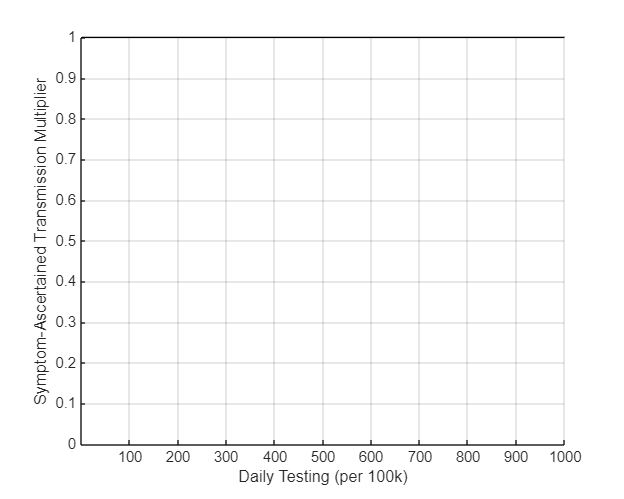

f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
surf(Y,Y,tr_mult_s);
set(gca,'XScale','linear');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Testing (per 100k)');
ylabel('');
zlabel('Symptom-Ascertained Transmission Multiplier');
view(0,0);

## Tracing-Ascertained Transmission Multiplier

For those ascertained via contact tracing (all asymptomatics and % of symptomatics), the transmission multiplier depends on the onset-PCR result/quarantine delay for traced contacts (where we assume that the infection-PCR result/quarantine delay is the same for asymptomatics and symptomatics), with data from:

- CN (PCR result) [https://www.thelancet.com/cms/10.1016/S1473-3099(20)30287-5/attachment/fde0cd38-f985-499f-9595-6578e367930c/mmc2.pdf](https://www.thelancet.com/cms/10.1016/S1473-3099(20)30287-5/attachment/fde0cd38-f985-499f-9595-6578e367930c/mmc2.pdf) 

- FN (quarantine) [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9817446/pdf/41598_2022_Article_27227.pdf](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9817446/pdf/41598_2022_Article_27227.pdf) 

- PT (quarantine: 6.5-4) [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9548448/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9548448/)

Note that there is an association between the testing rate and reduction in R ([https://www.nature.com/articles/s41598-021-03846-z](https://www.nature.com/articles/s41598-021-03846-z)), but that the delays also depend on incidence ([https://www.thelancet.com/pdfs/journals/lanwpc/PIIS2666-6065(21)00283-2.pdf](https://www.thelancet.com/pdfs/journals/lanwpc/PIIS2666-6065(21)00283-2.pdf),[https://www.gov.wales/sites/default/files/pdf-versions/2022/5/1/1653291976/test-trace-protect-contact-tracing-coronavirus-covid-19-7-may-2022.pdf](https://www.gov.wales/sites/default/files/pdf-versions/2022/5/1/1653291976/test-trace-protect-contact-tracing-coronavirus-covid-19-7-may-2022.pdf)).

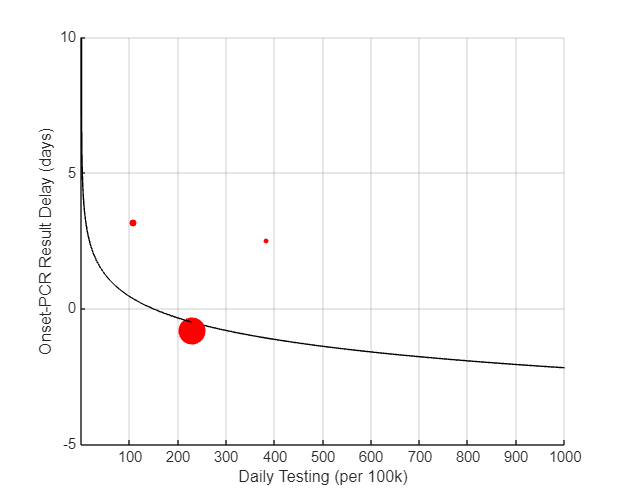

% read in delay data
data      = table({'China','Finland','Portugal'}',[NaN,NaN,NaN]',[98,1521,48]',[3.18,-0.8,2.5]', 'VariableNames', {'Country','trate','Sample','Value'});
countries = data.Country;

% read in testing data
T = readtable('../../../Data/Preparedness/10.testing.csv');
for i = 1:length(countries);
    country = countries{i};
    kr      = strcmp(T.Entity,country);

    date = T(kr,:).Date;
    dvec = datevec(date);
    dvec = dvec(:,1)-2020;
    date = day(date,'dayofyear')+366*min(1,dvec)+365*max(0,dvec-1);
    Tts  = 100*T(kr,:).CumulativeTotalPerThousand;
    Tts  = max(fillmissing(Tts,'linear'),0);
    
    fdat       = 1:850';
    fTts       = nan(size(fdat));
    fTts(date) = Tts;
    fTts       = max(fillmissing(fTts,'linear'),0);
    
    daily = movmean(diff(fTts),[0 30]);
    i_tit = find(daily>1,1);
    if ~isempty(i_tit);
        i_tit = i_tit+1;
        t_tit = fdat(i_tit);
    else
        i_tit = 367;
        t_tit = 367; 
    end
    t_end = 731;
    i_end = find(fdat==t_end,1);
    tspan = t_end-t_tit;
    Tspan = fTts(i_end)-fTts(i_tit-1);
    trate = Tspan/tspan;

    data.trate(i) = trate;
end

% quantities
x = data.trate(~isnan(data.Value));
y = data.Value(~isnan(data.Value));
w = data.Sample(~isnan(data.Value));

% fits
customfit2d     = fittype('11.3224-2.6260*log10(x)+c');%same as curve above, translated by constant
options         = fitoptions(customfit2d);
options.Weights = w;
[mdl,~]         = fit(x,y,customfit2d,options);%%%
onsetPCR_c      = reshape(feval(mdl,Y(:)),size(Y));
opc             = mdl.c/(4.6+((1-0.595)*(2.1)+0.595*(4)));%assume that the the time difference between those ascertained via symptoms and tracing scales with the generation time

% transmission multiplier
Tlat      = 4.6;
Tinc      = 5.8;
Tinf      = 2.1;%for asympomatics, 4 for symptomatics (for Covid)
Tinf_eff  = max(0,Tinc+onsetPCR_c-Tlat);
tr_mult_c = min(Tinf_eff,Tinf)./Tinf;

% figures
f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
msize = max(0.1,min(2*w,5000));
scatter3(x,x,y,msize,'r.');
surf(Y,Y,onsetPCR_c);
set(gca,'XScale','linear');
axis([10^-3 10^3 10^-3 10^3 -5 10]);
grid on;
xlabel('Daily Testing (per 100k)');
ylabel('');
zlabel('Onset-PCR Result Delay (days)');
view(0,0);

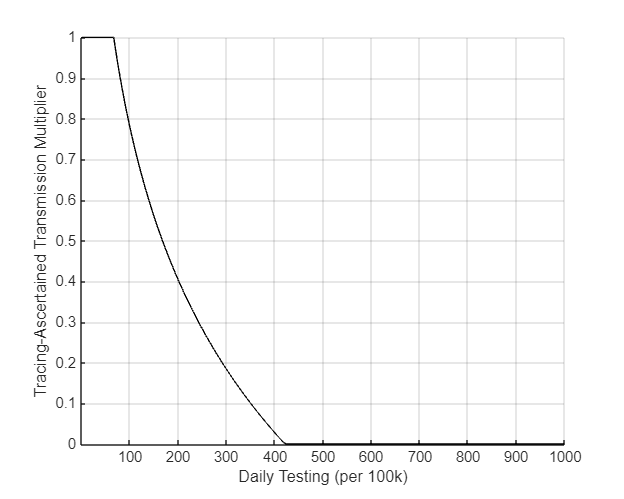

f = figure('Units','centimeters','Position',[0 0 15 12]);
hold on;
surf(Y,Y,tr_mult_c);
set(gca,'XScale','linear');
axis([10^-3 10^3 10^-3 10^3 0 1]);
grid on;
xlabel('Daily Testing (per 100k)');
ylabel('');
zlabel('Tracing-Ascertained Transmission Multiplier');
view(0,0);

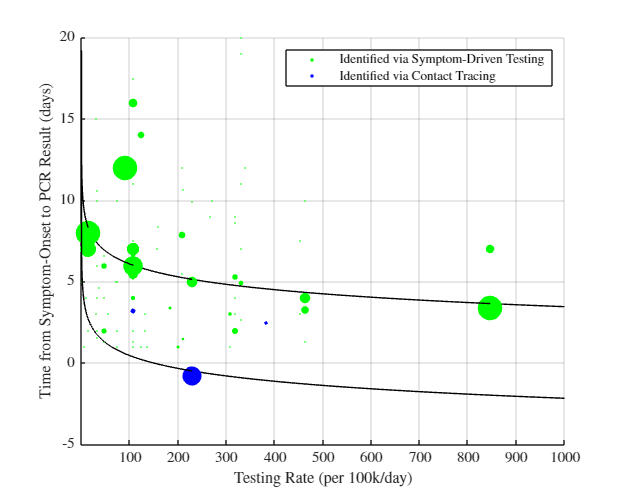


% figures
f = figure('Units','centimeters','Position',[0 0 15 12]);
set(f,'defaulttextInterpreter','latex');
set(f,'defaultAxesTickLabelInterpreter','latex');
set(f,'defaultLegendInterpreter','latex');
hold on;
msize = max(0.1,min(2*str.w,5000)/2);
h1 = scatter3(str.x,str.x,str.y,msize,'g.');
surf(Y,Y,str.onsetPCR_s);
msize = max(0.1,min(2*w,5000)/2);
h2 = scatter3(x,x,y,msize,'b.');
surf(Y,Y,onsetPCR_c);
set(gca,'XScale','linear');
axis([10^-3 10^3 10^-3 10^3 -5 20]);
grid on;
legend([h1, h2], {'Identified via Symptom-Driven Testing', 'Identified via Contact Tracing'}, 'Location', 'northeast');
xlabel('Testing Rate (per 100k/day)');
ylabel('');
zlabel('Time from Symptom-Onset to PCR Result (days)');
view(0,0);